## State feedback design with integral action

Your task is to replace all XXX below with the correct expressions.

%clear all
syms zeta omega_0 k k1 k2 K_f K_i real
syms s complex

### Form 2nd-order open-loop system


$$\dot{x} = Ax+Bu$$



$$y = Cx$$


System is given by the ODE


$$\ddot{q}+2\zeta\omega_0\dot{q}+\omega_0^2=k\omega_0^2u$$



$$y=q$$


omega_0 = 1;
zeta = 0.5;
k = 0.5;

Let $x_1 = q$ and $x_2 = \dot{q}$, then 

A = [0 1; -omega_0^2 -2*zeta*omega_0] 

A =      0     1
    -1    -1


B = [0; k*omega_0^2]

B =          0
    0.5000


C = [1 0]

$$pA = s^{2}+s+1$$

### Design a state feedback controller with integral action by eigenvalue assignment 

We want to design a controller such that


$$\lim_{t \rightarrow \infty} y(t) = r$$


for a constant reference $r$, even in the presence of plant-model mismatch and an input disturbance. 

The control law should be given by


$$u = K x + K_i z + K_f r $$


where the controller dynamics is given by

 
$$\dot{z} = y-r$$


Substitute the above expressions into the expression for the open-loop system to get the expression for the closed-loop system 


$$\dot{w} = A_{cl} w + B_{cl} r\\
y = C_{cl} w + D_{cl} r$$


with augmented state $w = [x'\ z']'$.

n = size(A,1); % number of states
K = [k1 k2]

$$K = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

Acl = [XXX XXX; XXX 0]

$$Acl = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{k_{1}}{2}-1 & \frac{k_{2}}{2}-1 & \frac{K_{i}}{2}\\ 1 & 0 & 0 \end{array}\right)$$

Bcl = [XXX; XXX]

$$Bcl = \left(\begin{array}{c} 0\\ \frac{K_{f}}{2}\\ -1 \end{array}\right)$$

Ccl = [C zeros(1,n-1)] % only interested in setting y = q = x1 = r

Ccl =      1     0     0


Dcl = 0

Dcl = 0

Compute coefficients `ccl` of characteristic polynomial `pcl` of closed-loop dynamics matrix `Acl`

pcl = collect(det(s*eye(n+1)-XXX))

$$pcl = s^{3}+\left(1-\frac{k_{2}}{2}\right)\,s^{2}+\left(1-\frac{k_{1}}{2}\right)\,s-\frac{K_{i}}{2}$$

ccl = coeffs(pcl,s)

$$ccl = \left(\begin{array}{cccc} -\frac{K_{i}}{2} & 1-\frac{k_{1}}{2} & 1-\frac{k_{2}}{2} & 1 \end{array}\right)$$

Compute desired coefficients `cd` of desired characteristic polynomial `pd` for `Acl. `

`N`ote that `Acl` is of size $(n+1)\times(n+1)$, because of the added integrator dynamic. Hence, the desired polynomial has to be of degree $n+1$.

pd = expand((s+2)^2*(s+3)) % place eigenvalues at -2, -2 and -3

$$pd = s^{3}+7\,s^{2}+16\,s+12$$

cd = coeffs(pd,s)

$$cd = \left(\begin{array}{cccc} 12 & 16 & 7 & 1 \end{array}\right)$$

 
eqns = ccl == cd % set expressions for coefficients equal to each other

$$eqns = \left(\begin{array}{cccc} -\frac{K_{i}}{2}=12 & 1-\frac{k_{1}}{2}=16 & 1-\frac{k_{2}}{2}=7 & 1=1 \end{array}\right)$$

Ks = solve(eqns,[k1 k2 K_i]); % solve for controller gains
k1 = Ks.k1

$$k1 = -30$$

k2 = Ks.k2

$$k2 = -12$$

K_i = Ks.K_i

$$K\_i = -24$$

## Form controller and closed-loop system to explore the effect of model error and an input disturbance

K = [k1 k2]

$$K = \left(\begin{array}{cc} -30 & -12 \end{array}\right)$$

K_f = -1/(C*((A-B*K)\B))

$$K\_f = -28$$

Recall that the controller is given by

 
$$\dot{z} = y-r=q-r=x_1-r$$



$$u = K x + K_i z + K_f r =  K_i z +K x +  K_f r$$


Hence the *input* to the controller is $[x_1\ x_2\ r]'$ and the *output* of the controller is $u$. The controller state is $z$.

Acontrol = XXX

Acontrol = 0

Bcontrol = XXX 

Bcontrol =      1     0    -1


Ccontrol = double(XXX)

Ccontrol = -24

Dcontrol = double(XXX)

Dcontrol =    -30   -12   -28


controller  = ss(Acontrol,Bcontrol,Ccontrol,Dcontrol,'InputName',{'x1','x2','r'}','OutputName','u','StateName',{'z'})

controller =
 
  A = 
      z
   z  0
 
  B = 
      x1  x2   r
   z   1   0  -1
 
  C = 
        z
   u  -24
 
  D = 
       x1   x2    r
   u  -30  -12  -28
 
Continuous-time state-space model.



eB = 0.9; % model error multiplier (me = 1 if no modelling error); try changing between 1 and 0.9
eA = 1.1; % model error multiplier (me = 1 if no modelling error); try changing between 1 and 1.1
% modify dynamics and input matrices and add an input disturbance
process = ss(double(A*eA), double([B B]*eB), eye(2), 0 ,'InputName',{'u','disturbance'},'OutputName',{'x1', 'x2'},'StateName',{'x1', 'x2'})

process =
 
  A = 
         x1    x2
   x1     0   1.1
   x2  -1.1  -1.1
 
  B = 
                 u  disturbance
   x1            0            0
   x2         0.45         0.45
 
  C = 
       x1  x2
   x1   1   0
   x2   0   1
 
  D = 
                 u  disturbance
   x1            0            0
   x2            0            0
 
Continuous-time state-space model.



clsys = connect(process,controller,{'r','disturbance'},{'x1', 'x2', 'u'}) % closed-loop system

clsys =
 
  A = 
          x1     x2      z
   x1      0    1.1      0
   x2  -14.6   -6.5  -10.8
   z       1      0      0
 
  B = 
                 r  disturbance
   x1            0            0
   x2        -12.6         0.45
   z            -1            0
 
  C = 
        x1   x2    z
   x1    1    0    0
   x2    0    1    0
   u   -30  -12  -24
 
  D = 
                 r  disturbance
   x1            0            0
   x2            0            0
   u           -28            0
 
Continuous-time state-space model.



damp(clsys) % closed-loop system

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.25e+00                 1.00e+00       1.25e+00         7.99e-01    
 -2.62e+00 + 1.61e+00i     8.52e-01       3.08e+00         3.81e-01    
 -2.62e+00 - 1.61e+00i     8.52e-01       3.08e+00         3.81e-01    


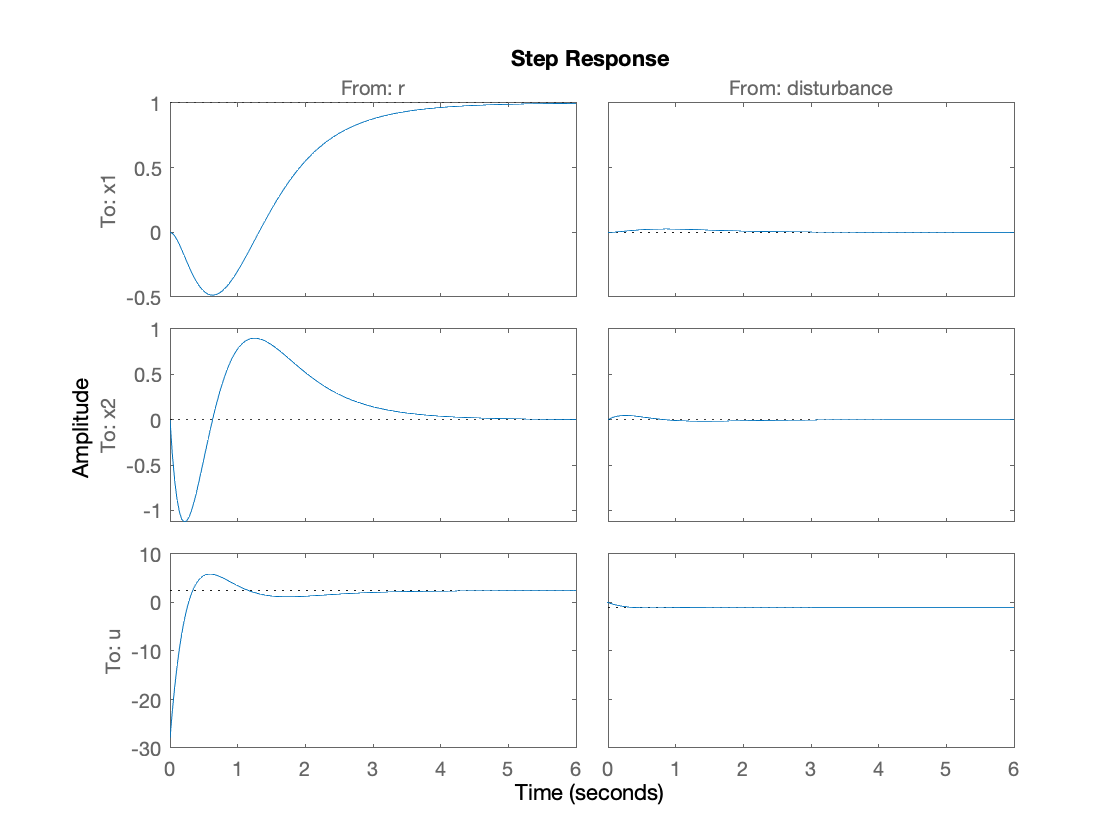

step(clsys) % closed-loop system

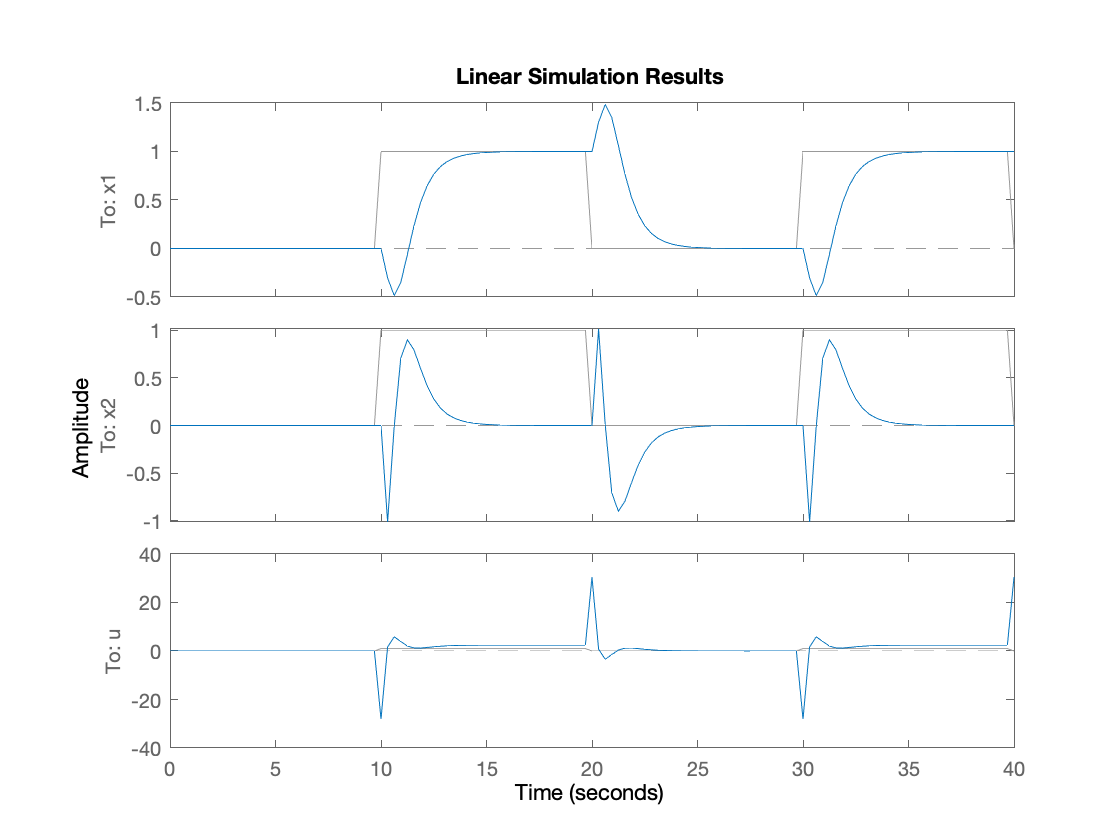

[sig,t] = gensig("square",20,40);
x0 = zeros(n,1);
z0 = 0; % set integrator initial condition to 0
lsim(clsys,[sig 0*sig],t,[x0; z0]) % no initial state estimate error, r = sig, disturbance = 0

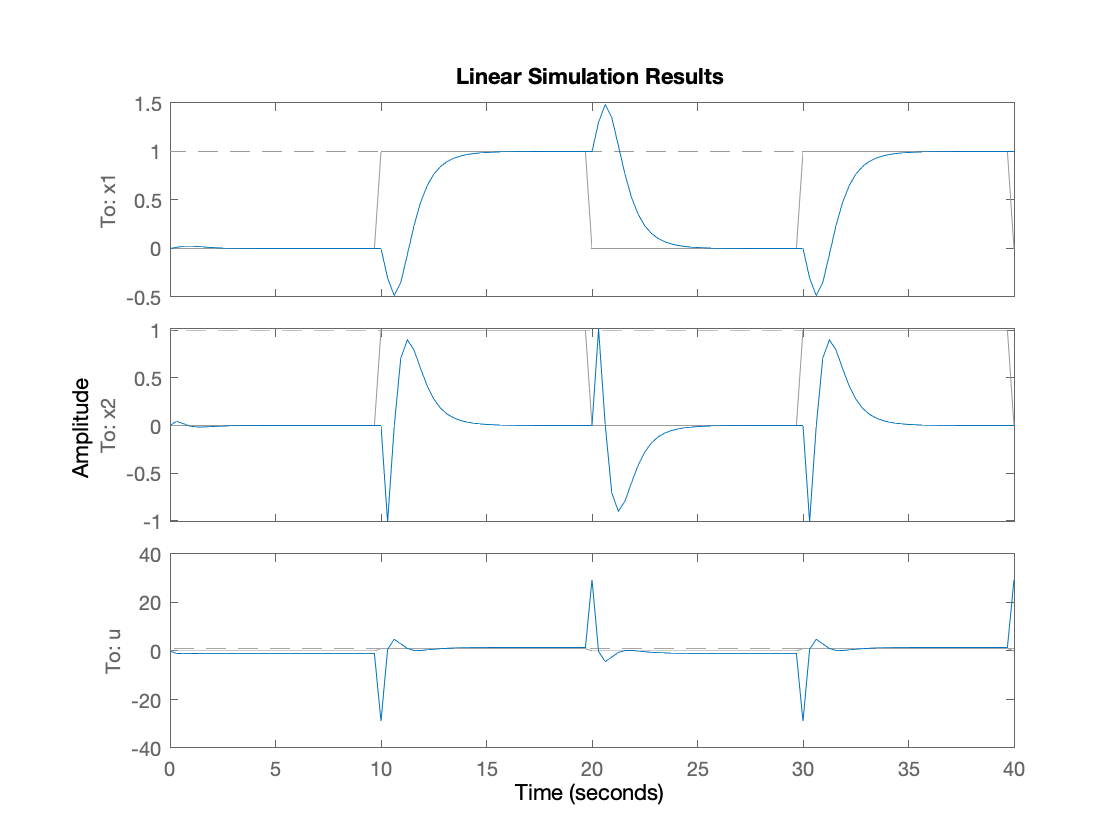

lsim(clsys,[sig ones(length(t),1)],t,[x0; z0]) % r = sig, disturbance = 1

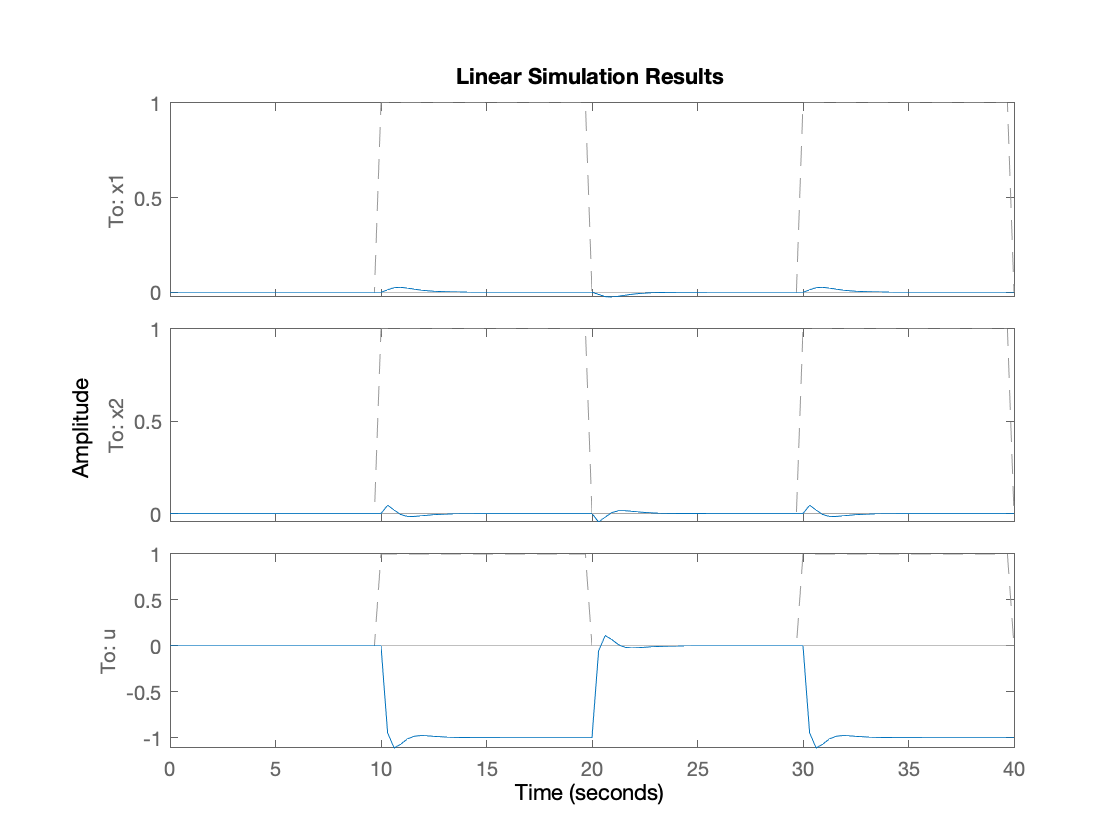

lsim(clsys,[0*sig sig],t,[x0; z0]) % no initial state estimate error, r = 0, disturbance = sig